# Geometric Mechanics on a discretely compliant robot with controllable pin constraint

In this work, we use Geometric Mechanics framework to motion plan for a discretely-soft, closed kinematic chain articulated, insect-sized quadrupedal robot with electroadhesive feet - CLARI (Compliant Legged Articulated Robotic Insect). We study a SE(2) in-plane of locomotion model to study the robot's *selective-stick-slip *motion.

## Robot Description and Problem Preliminaries

In the locomotion plane, the body of the robot is a quadrilateral with all the sides equally long. Since the body of the robot is made with carbon-fiber based laminates, it is light and the articulations are flexures (think of it as torsionally springy revolute joints with the rotation axis sticking out of the locomotion plane). **After applying the appropriate kinematic constraints, we only need one *****parameter ***$\gamma$** to describe the complete state of the body.**

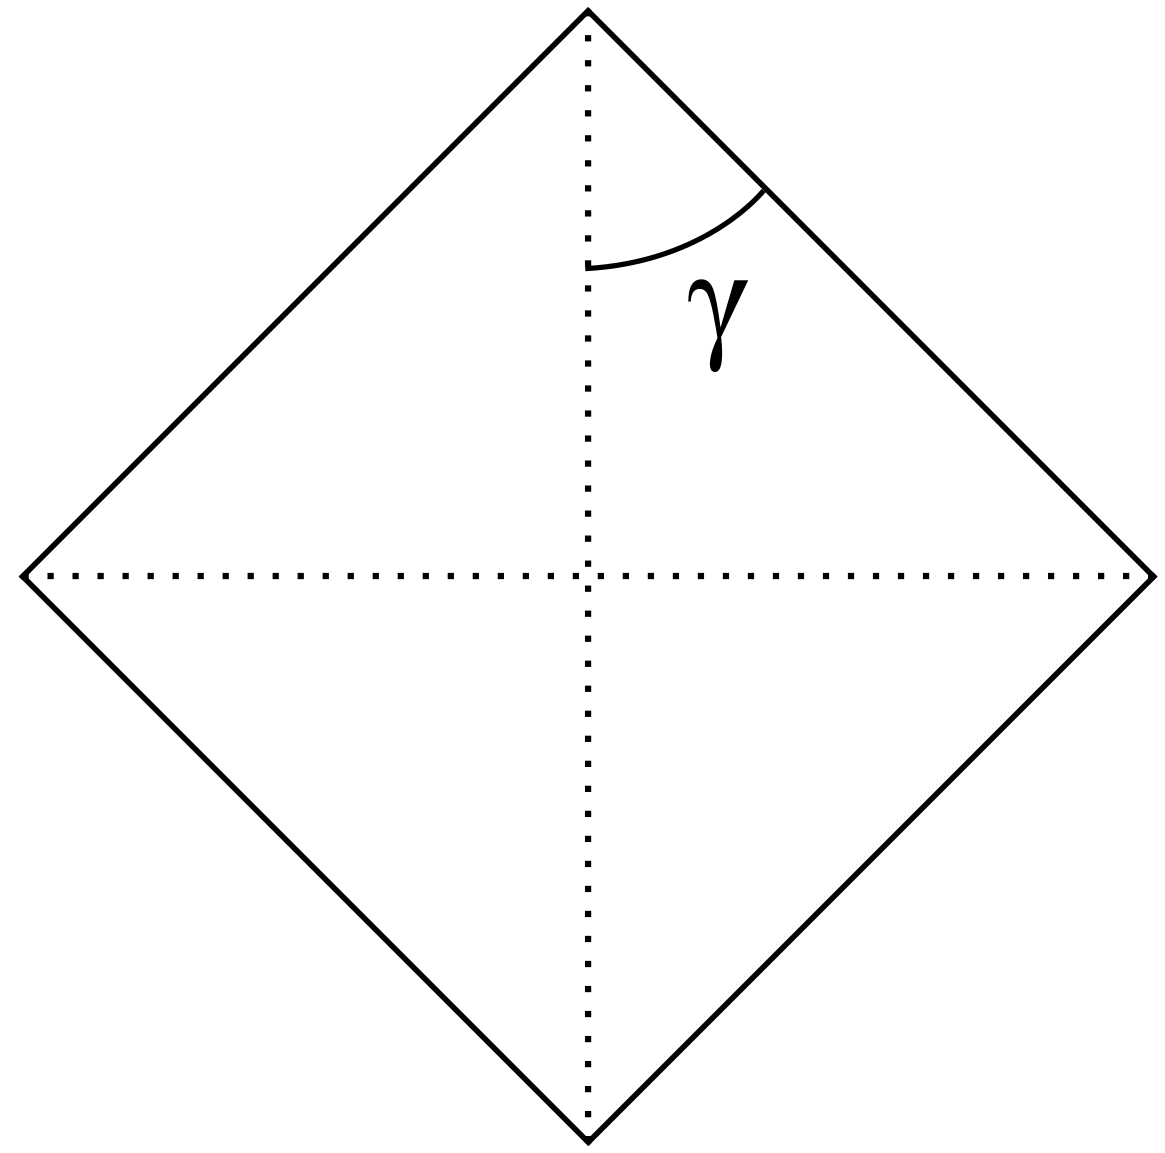 

The leg are labelled based on their location in the body --  the leg shown below is the labelled as 'front-right' FR, and $\beta_{TR}$ describes the corresponding leg angle. The length of the each side is considered as $2l$ and the length of each leg is $al$, where $a$ is the leg-fraction design parameter (we hope to tune this value to obtain a useful and easy to implement locomotion manifold).

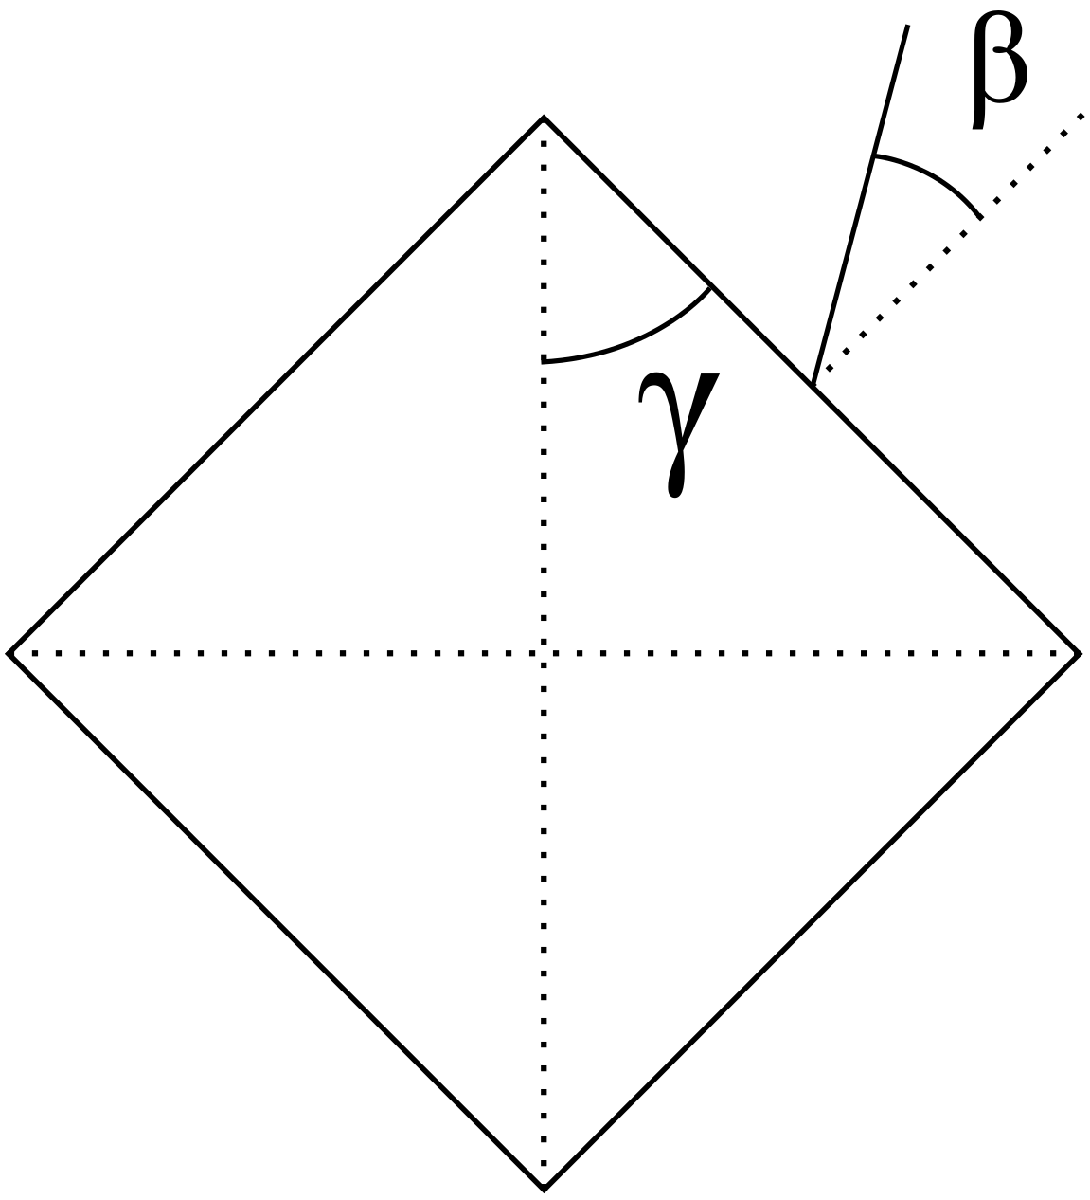

Now, armed with this information, we can start thinking about formulating **the problem where the adjacent legs of the robot are electro-adhered to the terrain for bound-like electro-adhered locomotion.**

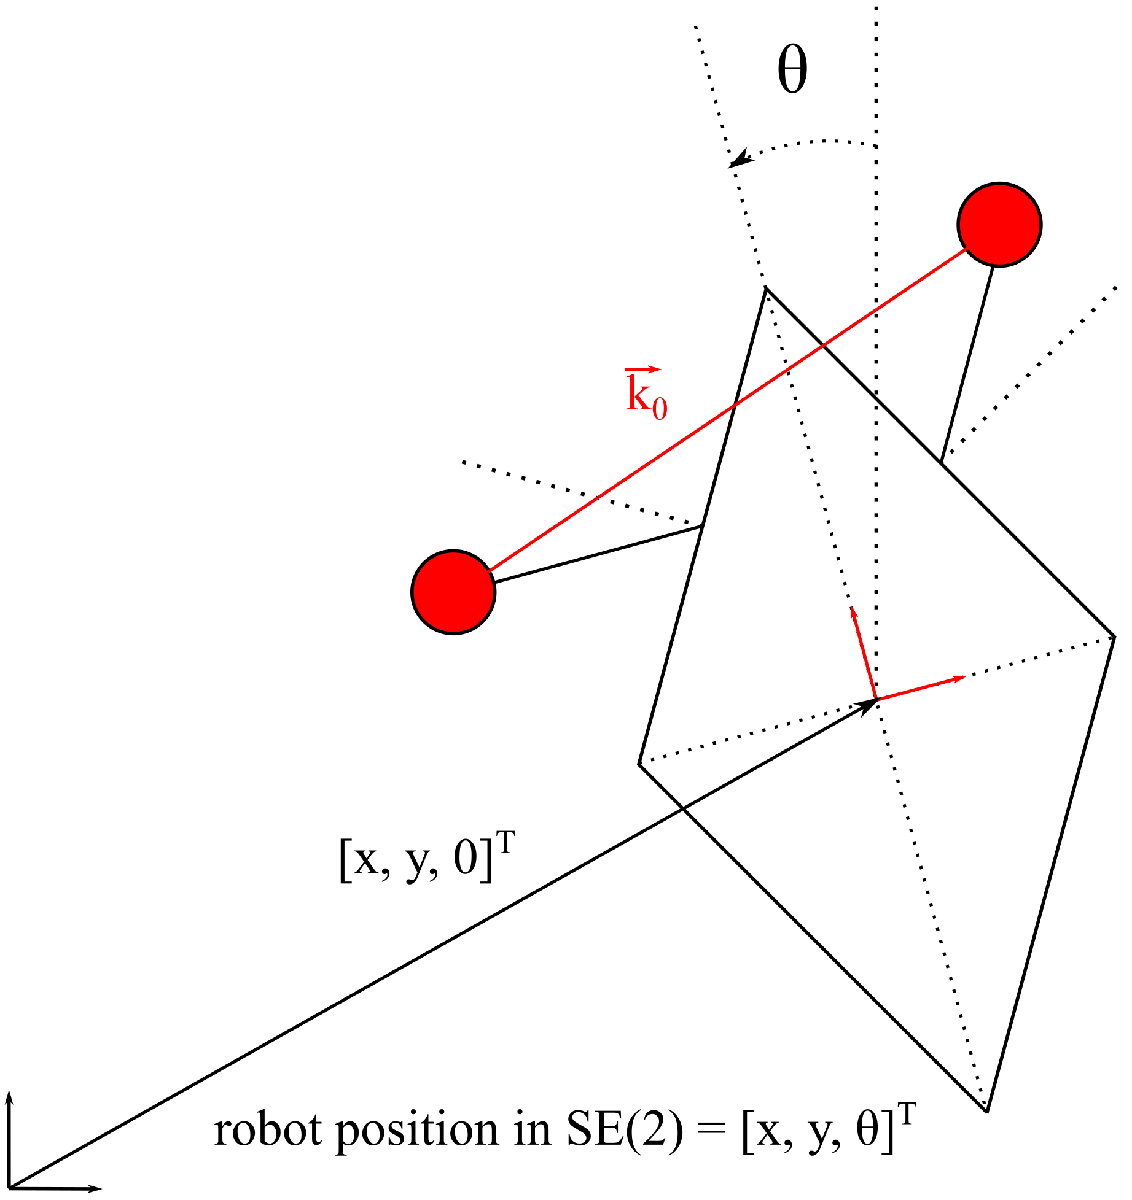

In the above figure, we describe the key-parameters for the problem are highlighted. When the active leg-pairs undergo a single stride, we assume the impact of the passive legs to be negligible. **The active leg-tip positions remain unchanged in the global frame throughout the stride.** Also, leg and body angles will be defined symbolically as temporal functions (or functions of the gait-phase $`\phi'$ which neaFLy eliminates the *frequency dependence *in the equivant temporal $`t'$ representation). This formulation can be easily extended to the opposite legs case by considering leg-pairs FR and BL, or FL and BR. This convention is similar to what's followed in [https://scholar.google.com/scholar?oi=bibs&cluster=5306644131620420498&btnI=1&hl=en.](https://scholar.google.com/scholar?oi=bibs&cluster=5306644131620420498&btnI=1&hl=en.)

## Nonlinear Motion Constraint

In the body frame the midpoint of each side is given as follows,

%%% Nonlinear Motion Constraint

% Since we are creating temporal functions, we can't make impose the real 
% assumption on them (MORE LIKE MAFLAB doesn't let you!). 
% Hence, we impose them on the initial conditions (IC) instead. Same recipe is
% followed for the leg angle ICs.
syms gamma_0 real 
syms gamma(phi)
condT_gamma = gamma(0) == gamma_0;

syms l real
s_FR = l*[sin(gamma); cos(gamma); 0]

$$s\_FR(phi) = \left(\begin{array}{c} l\,\sin\left(\gamma \left(\varphi \right)\right)\\ l\,\cos\left(\gamma \left(\varphi \right)\right)\\ 0 \end{array}\right)$$

s_FL = l*[-sin(gamma); cos(gamma); 0]

$$s\_FL(phi) = \left(\begin{array}{c} -l\,\sin\left(\gamma \left(\varphi \right)\right)\\ l\,\cos\left(\gamma \left(\varphi \right)\right)\\ 0 \end{array}\right)$$

Locally, the corresponding legs can be defined as shown below (we rotate and scale the body frame x-axis into the corresponding leg position),

rotMat = @(z) [cos(z), -sin(z), 0;
                sin(z), cos(z), 0;
                0, 0, 1];
xHat = [1, 0, 0]';

syms beta_FR0 beta_FL0 real % initial leg angles as the start to adhere
syms beta_FR(phi) beta_FL(phi)
condT_beta = [beta_FR(0) == beta_FR0, beta_FL(0) == beta_FL0];

syms a real % the leg-link length fraction
l_FR = a*l*rotMat(gamma + beta_FR)*xHat

$$l\_FR(phi) = \left(\begin{array}{c} a\,l\,\cos\left(\beta_{\mathrm{FR}}\left(\varphi \right)+\gamma \left(\varphi \right)\right)\\ a\,l\,\sin\left(\beta_{\mathrm{FR}}\left(\varphi \right)+\gamma \left(\varphi \right)\right)\\ 0 \end{array}\right)$$

l_FL = a*l*rotMat(pi - gamma + beta_FL)*xHat

$$l\_FL(phi) = \left(\begin{array}{c} -a\,l\,\cos\left(\beta_{\mathrm{FL}}\left(\varphi \right)-\gamma \left(\varphi \right)\right)\\ -a\,l\,\sin\left(\beta_{\mathrm{FL}}\left(\varphi \right)-\gamma \left(\varphi \right)\right)\\ 0 \end{array}\right)$$

Now, we can combine the leg and side descriptions to obtain the **location of the leg-tip from the body frame origin**,

L_FR = s_FR + l_FR

$$L\_FR(phi) = \left(\begin{array}{c} l\,\sin\left(\gamma \left(\varphi \right)\right)+a\,l\,\cos\left(\beta_{\mathrm{FR}}\left(\varphi \right)+\gamma \left(\varphi \right)\right)\\ l\,\cos\left(\gamma \left(\varphi \right)\right)+a\,l\,\sin\left(\beta_{\mathrm{FR}}\left(\varphi \right)+\gamma \left(\varphi \right)\right)\\ 0 \end{array}\right)$$

L_FL = s_FL + l_FL

$$L\_FL(phi) = \left(\begin{array}{c} -l\,\sin\left(\gamma \left(\varphi \right)\right)-a\,l\,\cos\left(\beta_{\mathrm{FL}}\left(\varphi \right)-\gamma \left(\varphi \right)\right)\\ l\,\cos\left(\gamma \left(\varphi \right)\right)-a\,l\,\sin\left(\beta_{\mathrm{FL}}\left(\varphi \right)-\gamma \left(\varphi \right)\right)\\ 0 \end{array}\right)$$

Lets represent the leg-tip vectors in the global frame and impose that they are constant over the duration of the stride,

syms x_0 y_0 theta_0 real
syms x(phi) y(phi) theta(phi)
condT_Pos = [x(0) == y_0, x(0) == y_0, theta(0) == theta_0];

% Rewrite the leg description in the global frame:
gL_FR = simplify([x; y; 0] + rotMat(theta)*L_FR)

$$gL\_FR(phi) = \left(\begin{array}{c} x\left(\varphi \right)+l\,\sin\left(\gamma \left(\varphi \right)-\theta \left(\varphi \right)\right)+a\,l\,\cos\left(\beta_{\mathrm{FR}}\left(\varphi \right)+\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right)\\ y\left(\varphi \right)+l\,\cos\left(\gamma \left(\varphi \right)-\theta \left(\varphi \right)\right)+a\,l\,\sin\left(\beta_{\mathrm{FR}}\left(\varphi \right)+\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right)\\ 0 \end{array}\right)$$

gL_FL = simplify([x; y; 0] + rotMat(theta)*L_FL)

$$gL\_FL(phi) = \left(\begin{array}{c} x\left(\varphi \right)-l\,\sin\left(\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right)-a\,l\,\cos\left(\beta_{\mathrm{FL}}\left(\varphi \right)-\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right)\\ y\left(\varphi \right)+l\,\cos\left(\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right)-a\,l\,\sin\left(\beta_{\mathrm{FL}}\left(\varphi \right)-\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right)\\ 0 \end{array}\right)$$

**Finally, we impose the electro-adhered stride constraint (highly nonlinear) through a gait-phase **$\phi$** derivative of the leg-position vectors,**

condT_stride_FR = diff(gL_FR) == [0;0;0]

$$condT\_stride\_FR(phi) = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial \varphi }x\left(\varphi \right)+l\,\cos\left(\gamma \left(\varphi \right)-\theta \left(\varphi \right)\right)\,\sigma_{2}-a\,l\,\sin\left(\sigma_{3}\right)\,\sigma_{1}=0\\ \frac{\partial }{\partial \varphi }y\left(\varphi \right)-l\,\sin\left(\gamma \left(\varphi \right)-\theta \left(\varphi \right)\right)\,\sigma_{2}+a\,l\,\cos\left(\sigma_{3}\right)\,\sigma_{1}=0\\ 0=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial \varphi }\beta_{\mathrm{FR}}\left(\varphi \right)+\frac{\partial }{\partial \varphi }\gamma \left(\varphi \right)+\frac{\partial }{\partial \varphi }\theta \left(\varphi \right)\\ \sigma_{2}=\frac{\partial }{\partial \varphi }\gamma \left(\varphi \right)-\frac{\partial }{\partial \varphi }\theta \left(\varphi \right)\\ \sigma_{3}=\beta_{\mathrm{FR}}\left(\varphi \right)+\gamma \left(\varphi \right)+\theta \left(\varphi \right) \end{array}$$

condT_stride_FL = diff(gL_FL) == [0;0;0]

$$condT\_stride\_FL(phi) = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial \varphi }x\left(\varphi \right)-l\,\cos\left(\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right)\,\sigma_{2}+a\,l\,\sin\left(\sigma_{3}\right)\,\sigma_{1}=0\\ \frac{\partial }{\partial \varphi }y\left(\varphi \right)-l\,\sin\left(\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right)\,\sigma_{2}-a\,l\,\cos\left(\sigma_{3}\right)\,\sigma_{1}=0\\ 0=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial \varphi }\beta_{\mathrm{FL}}\left(\varphi \right)-\frac{\partial }{\partial \varphi }\gamma \left(\varphi \right)+\frac{\partial }{\partial \varphi }\theta \left(\varphi \right)\\ \sigma_{2}=\frac{\partial }{\partial \varphi }\gamma \left(\varphi \right)+\frac{\partial }{\partial \varphi }\theta \left(\varphi \right)\\ \sigma_{3}=\beta_{\mathrm{FL}}\left(\varphi \right)-\gamma \left(\varphi \right)+\theta \left(\varphi \right) \end{array}$$

Before, we start to think about linearizing this, let's express the initial position of the adhered legs,

% Let's substitute the ICs to obtain the positions of the legs as soon as
% they adhere:
gL_FR0 = subs(gL_FR, [x y theta beta_FR gamma], [x_0 y_0 theta_0 beta_FR0 gamma_0])

$$gL\_FR0(phi) = \left(\begin{array}{c} x_{0}+l\,\sin\left(\gamma_{0}-\theta_{0}\right)+a\,l\,\cos\left(\beta_{\mathrm{FR0}}+\gamma_{0}+\theta_{0}\right)\\ y_{0}+l\,\cos\left(\gamma_{0}-\theta_{0}\right)+a\,l\,\sin\left(\beta_{\mathrm{FR0}}+\gamma_{0}+\theta_{0}\right)\\ 0 \end{array}\right)$$

gL_FL0 = subs(gL_FL, [x y theta beta_FL gamma], [x_0 y_0 theta_0 beta_FL0 gamma_0])

$$gL\_FL0(phi) = \left(\begin{array}{c} x_{0}-l\,\sin\left(\gamma_{0}+\theta_{0}\right)-a\,l\,\cos\left(\beta_{\mathrm{FL0}}-\gamma_{0}+\theta_{0}\right)\\ y_{0}+l\,\cos\left(\gamma_{0}+\theta_{0}\right)-a\,l\,\sin\left(\beta_{\mathrm{FL0}}-\gamma_{0}+\theta_{0}\right)\\ 0 \end{array}\right)$$

## Linearizing the Constraint

**Here, we use **$\mathrm{1^{st}}$** order taylor's approximation to obtain the linearized pfaffian constraints that will help us generate the linearized reconstruction equation. But, we can also choose to work with the nonlinear form of the equation since the nonlinearities only impact the parameters of the global and shape velocities. **But, before we proceed, we establish some more preliminaries that will help us work in this *discretized gait-phase space. *We can linearize the system at discrete $\phi$ instants based on the data from the previous instant $\phi^-$. The nonlinear functions are implicit functions of $\phi$, and are explicit functions of say $x$. We represent $x(\phi)$ as simply $x$ and $x(\phi^-)$ as $x^-$. The coding variable for $x^-$ will be $\mathrm{\hat{x}}$.

%%% Linearizing the Constraint

% Define the position parameters at the previous `phi' instant
syms x__m y__m theta__m gamma__m beta_FR__m beta_FL__m real

% We only have Sine and Cosine nonlinearities, and hence, we only
% approximate those
syms delta delta_hat
% Order of the approximation needs to be one more the variable power to get
% the desired form
SineApprox = taylor(sin(delta), delta, delta_hat, 'Order', 2)

$$SineApprox = \sin\left(\hat{\delta }\right)+\cos\left(\hat{\delta }\right)\,\left(\delta -\hat{\delta }\right)$$

CosineApprox = taylor(cos(delta), delta, delta_hat, 'Order', 2)

$$CosineApprox = \cos\left(\hat{\delta }\right)-\sin\left(\hat{\delta }\right)\,\left(\delta -\hat{\delta }\right)$$

As an example, we display the approxmiation of one of the terms in the FR leg condition, below,

% GT - Gamma Theta Term; BGT - Beta Gamma Theta Term
% FR terms
C_GT_FR = subs(CosineApprox, [delta, delta_hat], [gamma - theta, gamma__m - theta__m])

$$C\_GT\_FR = \cos\left(\gamma^{m}-\theta^{m}\right)+\sin\left(\gamma^{m}-\theta^{m}\right)\,\left(\gamma^{m}-\theta^{m}-\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right)$$

S_GT_FR = subs(SineApprox, [delta, delta_hat], [gamma - theta, gamma__m - theta__m]);
C_BGT_FR = subs(CosineApprox, [delta, delta_hat], [beta_FR + gamma + theta, beta_FR__m + gamma__m + theta__m]);
S_BGT_FR = subs(SineApprox, [delta, delta_hat], [beta_FR + gamma + theta, beta_FR__m + gamma__m + theta__m]);

% FL terms
C_GT_FL = subs(CosineApprox, [delta, delta_hat], [gamma + theta, gamma_0 + theta__m]);
S_GT_FL = subs(SineApprox, [delta, delta_hat], [gamma + theta, gamma_0 + theta__m]);
C_BGT_FL = subs(CosineApprox, [delta, delta_hat], [beta_FL - gamma + theta, beta_FL__m - gamma__m + theta__m]);
S_BGT_FL = subs(SineApprox, [delta, delta_hat], [beta_FL - gamma + theta, beta_FL__m - gamma__m + theta__m]);


**The linear global leg position constraints are shown below,**

condT_stride_FR_linear = subs(condT_stride_FR, [cos(gamma - theta), sin(gamma - theta), ...
    cos(beta_FR + gamma + theta), sin(beta_FR + gamma + theta)],...
    [C_GT_FR, S_GT_FR, C_BGT_FR, S_BGT_FR]);
condT_stride_FL_linear = subs(condT_stride_FL, [cos(gamma + theta), sin(gamma + theta), ...
    cos(beta_FL - gamma + theta), sin(beta_FL - gamma + theta)],...
    [C_GT_FL, S_GT_FL, C_BGT_FL, S_BGT_FL]);

% Let's do the linearization for the global leg-tip velocity symbolic
% functions
gV_FR_nonlin = diff(gL_FR(phi)); gV_FL_nonlin = diff(gL_FL(phi));

gV_FR_lin = subs(diff(gL_FR(phi)), [cos(gamma - theta), sin(gamma - theta), ...
    cos(beta_FL + gamma + theta), sin(beta_FL + gamma + theta)],...
    [C_GT_FR, S_GT_FR, C_BGT_FR, S_BGT_FR]);

gV_FL_lin = subs(diff(gL_FL(phi)), [cos(gamma + theta), sin(gamma + theta), ...
    cos(beta_FL - gamma + theta), sin(beta_FL - gamma + theta)],...
    [C_GT_FL, S_GT_FL, C_BGT_FL, S_BGT_FL]);

% Display the LHS of the constraints we shall use to obtain the locomotion
% jacobian
PfaffCondT_IsoForm_linear = [gV_FR_lin(1:2); gV_FL_lin(1:2)] % this form will let us isolate the constraints easily

PfaffCondT_IsoForm_nonlinear = [gV_FR_nonlin(1:2); gV_FL_nonlin(1:2)]

$$PfaffCondT\_IsoForm\_nonlinear = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial \varphi }x\left(\varphi \right)+l\,\cos\left(\sigma_{7}\right)\,\sigma_{3}-a\,l\,\sin\left(\sigma_{5}\right)\,\sigma_{1}\\ \frac{\partial }{\partial \varphi }y\left(\varphi \right)-l\,\sin\left(\sigma_{7}\right)\,\sigma_{3}+a\,l\,\cos\left(\sigma_{5}\right)\,\sigma_{1}\\ \frac{\partial }{\partial \varphi }x\left(\varphi \right)-l\,\cos\left(\sigma_{8}\right)\,\sigma_{4}+a\,l\,\sin\left(\sigma_{6}\right)\,\sigma_{2}\\ \frac{\partial }{\partial \varphi }y\left(\varphi \right)-l\,\sin\left(\sigma_{8}\right)\,\sigma_{4}-a\,l\,\cos\left(\sigma_{6}\right)\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial \varphi }\beta_{\mathrm{FR}}\left(\varphi \right)+\frac{\partial }{\partial \varphi }\gamma \left(\varphi \right)+\frac{\partial }{\partial \varphi }\theta \left(\varphi \right)\\ \sigma_{2}=\frac{\partial }{\partial \varphi }\beta_{\mathrm{FL}}\left(\varphi \right)-\frac{\partial }{\partial \varphi }\gamma \left(\varphi \right)+\frac{\partial }{\partial \varphi }\theta \left(\varphi \right)\\ \sigma_{3}=\frac{\partial }{\partial \varphi }\gamma \left(\varphi \right)-\frac{\partial }{\partial \varphi }\theta \left(\varphi \right)\\ \sigma_{4}=\frac{\partial }{\partial \varphi }\gamma \left(\varphi \right)+\frac{\partial }{\partial \varphi }\theta \left(\varphi \right)\\ \sigma_{5}=\beta_{\mathrm{FR}}\left(\varphi \right)+\gamma \left(\varphi \right)+\theta \left(\varphi \right)\\ \sigma_{6}=\beta_{\mathrm{FL}}\left(\varphi \right)-\gamma \left(\varphi \right)+\theta \left(\varphi \right)\\ \sigma_{7}=\gamma \left(\varphi \right)-\theta \left(\varphi \right)\\ \sigma_{8}=\gamma \left(\varphi \right)+\theta \left(\varphi \right) \end{array}$$


% Isolate the four conditions we have:
PfaffCondT_stride_adj_linear = [condT_stride_FR_linear(1:2); condT_stride_FL_linear(1:2)];

## Reconstruction Equation

Now, we can collect the terms since each we have 4 *Pfaffian constraints* (2 from the FR and 2 from the FL leg position conditions). For the uninitiated, the general form of $L$ number of such a constraints to describe a dynamical system is as follows,


$$\sum^n_{s-1} A_{rs} du_s + A_r dt = 0; r = [1,L] \cap \mathbf{Z}.$$


Let's call the global velocities as $\xi$ for the moment (following the convention ouFLined in https://scholar.google.com/scholar?oi=bibs&cluster=5306644131620420498&btnI=1&hl=en). The above constraints can be written in the following form,

$\omega(\alpha) [\xi, \dot{\alpha }]^T = [0, 0]^T$,

and then we divide the terms into two matrices (the first and second ones as linear functions of $\xi$ and $\dot{\alpha}$). Finally, we move terms to different sides of the equation, and invert the coefficient matrix of $\xi$ to get the ***Reconstruction Equation ***(where A is dubbed the ***Locomotion Jacobian***),

$\xi = A(\alpha) \dot{\alpha}$.

The above procedure is ouFLine in [https://link.springer.com/article/10.1140/epjst/e2015-50085-y](https://link.springer.com/article/10.1140/epjst/e2015-50085-y) and [https://scholar.google.com/scholar?oi=bibs&cluster=5306644131620420498&btnI=1&hl=en.](https://scholar.google.com/scholar?oi=bibs&cluster=5306644131620420498&btnI=1&hl=en.)

For our problem, we choose our shape-space and ***lifted global velocity*** as follows,


$$\dot{\alpha} = [\dot{\beta}_{TR}, \dot{\beta}_{TL}]^T,$$
 
$$\hat{\xi} = [\dot{x}, \dot{y}, \dot{\theta}, \mathbf{\dot{\gamma}}]^T.$$


We call this deviation from standard theory as *lifted *since we employ ***rate of change of sprawledness of this discretely-soft robot as a global velocity component. ***In other words, we believe, this uncontrolled/passive internal DOF of the robot (or how much space it occupies in body frame) is key to motion through in-plane clutter. But, this also means that the global velocoty no longer belongs to $\mathbf{SE(2)}$, and hence we can't use some of the following steps in the theory. <talk about terradynamics stuff, etc!>

% Obtain the indices of the omega matrix in the order of xi_hat
% components first, and followed by alpha_dot components.
omega = sym('omega%d%d',[numel(PfaffCondT_IsoForm_nonlinear) 6],'real')

$$omega = \left(\begin{array}{cccccc} \omega_{11} & \omega_{12} & \omega_{13} & \omega_{14} & \omega_{15} & \omega_{16}\\ \omega_{21} & \omega_{22} & \omega_{23} & \omega_{24} & \omega_{25} & \omega_{26}\\ \omega_{31} & \omega_{32} & \omega_{33} & \omega_{34} & \omega_{35} & \omega_{36}\\ \omega_{41} & \omega_{42} & \omega_{43} & \omega_{44} & \omega_{45} & \omega_{46} \end{array}\right)$$

Before we populate this matrix, below we show an example on obtaining the coefficient of $\frac{\partial}{\partial{\phi}} \theta(\phi)$ -- one our candidate terms as ouFLined in the vector $\hat{\xi}$. If our Pfaffian constraints were in a simple polynomial form, we can just pull out the terms by using the *collect *command, but since we have nonlinear constants, this doesn't seem to work to our favor.

PfaffCondT_IsoForm_nonlinear(1)

$$ans = \frac{\partial }{\partial \varphi }x\left(\varphi \right)+l\,\cos\left(\gamma \left(\varphi \right)-\theta \left(\varphi \right)\right)\,\left(\frac{\partial }{\partial \varphi }\gamma \left(\varphi \right)-\frac{\partial }{\partial \varphi }\theta \left(\varphi \right)\right)-a\,l\,\sin\left(\beta_{\mathrm{FR}}\left(\varphi \right)+\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right)\,\left(\frac{\partial }{\partial \varphi }\beta_{\mathrm{FR}}\left(\varphi \right)+\frac{\partial }{\partial \varphi }\gamma \left(\varphi \right)+\frac{\partial }{\partial \varphi }\theta \left(\varphi \right)\right)$$

diff(gamma)

$$ans(phi) = \frac{\partial }{\partial \varphi }\gamma \left(\varphi \right)$$

isolate(PfaffCondT_IsoForm_nonlinear(1) == 0, diff(theta))

$$ans = \begin{array}{l} \frac{\partial }{\partial \varphi }\theta \left(\varphi \right)=\frac{\frac{\partial }{\partial \varphi }x\left(\varphi \right)+l\,\cos\left(\gamma \left(\varphi \right)-\theta \left(\varphi \right)\right)\,\frac{\partial }{\partial \varphi }\gamma \left(\varphi \right)-a\,l\,\sigma_{1}\,\left(\frac{\partial }{\partial \varphi }\beta_{\mathrm{FR}}\left(\varphi \right)+\frac{\partial }{\partial \varphi }\gamma \left(\varphi \right)\right)}{l\,\cos\left(\gamma \left(\varphi \right)-\theta \left(\varphi \right)\right)+a\,l\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\beta_{\mathrm{FR}}\left(\varphi \right)+\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right) \end{array}$$

if has(PfaffCondT_IsoForm_nonlinear(1), diff(theta))
    [~,temp] = numden(rhs(isolate(PfaffCondT_IsoForm_nonlinear(1) == 0, diff(theta))));
    temp = -temp 
end

$$temp = -l\,\cos\left(\gamma \left(\varphi \right)-\theta \left(\varphi \right)\right)-a\,l\,\sin\left(\beta_{\mathrm{FR}}\left(\varphi \right)+\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right)$$

### Collecting the coefficients

With this, we can move on to populate the $\omega$ matrix. Getting the sign right is the hard part since *isolate* command works weirdly, so for now, we obtain the matrix and following this, we fix the signs manually.

% Now, we are going to loop over to fill up this matrix using isolate and
% rhs functions.
for k = 1:numel(PfaffCondT_IsoForm_nonlinear)
    for m = 1:6
        
        if m == 1
            symCoeff2Get = diff(x(phi));
        elseif m == 2
            symCoeff2Get = diff(y(phi));
        elseif m == 3
            symCoeff2Get = diff(theta(phi));
        elseif m == 4
            symCoeff2Get = diff(gamma(phi));
        elseif m == 5
            symCoeff2Get = diff(beta_FR(phi));
        elseif m == 6
            symCoeff2Get = diff(beta_FL(phi));
        end
        
        if has(PfaffCondT_IsoForm_nonlinear(k), symCoeff2Get)
            [~,omega(k,m)] = numden(rhs(isolate(PfaffCondT_IsoForm_nonlinear(k) == 0, symCoeff2Get)));
            omega(k,m) = simplify(omega(k,m));
        else
            omega(k,m) = 0;
        end
        
    end
end

omega

$$omega = \begin{array}{l} \left(\begin{array}{cccccc} 1 & 0 & \sigma_{3}+\sigma_{5} & \sigma_{3}-\sigma_{5} & \sigma_{5} & 0\\ 0 & 1 & \sigma_{1}+\sigma_{7} & \sigma_{1}-\sigma_{7} & \sigma_{7} & 0\\ 1 & 0 & \sigma_{4}-\sigma_{6} & \sigma_{4}+\sigma_{6} & 0 & \sigma_{6}\\ 0 & 1 & \sigma_{2}+\sigma_{8} & \sigma_{2}-\sigma_{8} & 0 & \sigma_{8} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l\,\sin\left(\gamma \left(\varphi \right)-\theta \left(\varphi \right)\right)\\ \sigma_{2}=l\,\sin\left(\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right)\\ \sigma_{3}=l\,\cos\left(\gamma \left(\varphi \right)-\theta \left(\varphi \right)\right)\\ \sigma_{4}=l\,\cos\left(\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right)\\ \sigma_{5}=a\,l\,\sin\left(\sigma_{9}\right)\\ \sigma_{6}=a\,l\,\sin\left(\sigma_{10}\right)\\ \sigma_{7}=a\,l\,\cos\left(\sigma_{9}\right)\\ \sigma_{8}=a\,l\,\cos\left(\sigma_{10}\right)\\ \sigma_{9}=\beta_{\mathrm{FR}}\left(\varphi \right)+\gamma \left(\varphi \right)+\theta \left(\varphi \right)\\ \sigma_{10}=\beta_{\mathrm{FL}}\left(\varphi \right)-\gamma \left(\varphi \right)+\theta \left(\varphi \right) \end{array}$$


% There are issues with this representaion since we don't get the right
% sign, so we manually fix the sigsn in some of these terms. Let's sort
% through each row in order.
omega(1,3) = -omega(1,3); omega(1,5) = -omega(1,5);
omega(2,4) = -omega(2,4);
omega(3,3) = -omega(3,3); omega(3,4) = -omega(3,4);
omega(4,3) = -omega(4,3); omega(4,4) = -omega(4,4); omega(4,6) = -omega(4,6);

omega

$$omega = \begin{array}{l} \left(\begin{array}{cccccc} 1 & 0 & -\sigma_{3}-\sigma_{5} & \sigma_{3}-\sigma_{5} & -\sigma_{5} & 0\\ 0 & 1 & \sigma_{1}+\sigma_{7} & \sigma_{7}-\sigma_{1} & \sigma_{7} & 0\\ 1 & 0 & \sigma_{6}-\sigma_{4} & -\sigma_{4}-\sigma_{6} & 0 & \sigma_{6}\\ 0 & 1 & -\sigma_{2}-\sigma_{8} & \sigma_{8}-\sigma_{2} & 0 & -\sigma_{8} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l\,\sin\left(\gamma \left(\varphi \right)-\theta \left(\varphi \right)\right)\\ \sigma_{2}=l\,\sin\left(\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right)\\ \sigma_{3}=l\,\cos\left(\gamma \left(\varphi \right)-\theta \left(\varphi \right)\right)\\ \sigma_{4}=l\,\cos\left(\gamma \left(\varphi \right)+\theta \left(\varphi \right)\right)\\ \sigma_{5}=a\,l\,\sin\left(\sigma_{9}\right)\\ \sigma_{6}=a\,l\,\sin\left(\sigma_{10}\right)\\ \sigma_{7}=a\,l\,\cos\left(\sigma_{9}\right)\\ \sigma_{8}=a\,l\,\cos\left(\sigma_{10}\right)\\ \sigma_{9}=\beta_{\mathrm{FR}}\left(\varphi \right)+\gamma \left(\varphi \right)+\theta \left(\varphi \right)\\ \sigma_{10}=\beta_{\mathrm{FL}}\left(\varphi \right)-\gamma \left(\varphi \right)+\theta \left(\varphi \right) \end{array}$$

Now, we can move on to obtaining the reconstruction equation with non-linear parameters. In short, we shall split $\omega \;$into two sub-matrices corresponding to the components of $\xi \;$and $\dot{\alpha \;}$. The equation should look something like this,

$\omega_1 \hat{\xi} = -\omega_2 \dot{\alpha}$.

After this, we need to take the inverse of $\omega_1$and **our *****locomotion jacobian A***** is essentially **$\omega_1^{-1} \;\omega_2$. It is important to note that we need to mindful of when such an inverse exists and when it doesn't exist what does that mean physically -- in other words, for that robot configuration (global location and shape), a solution doesn't exist. Paraphrasing this to our case, if the robot inter-leg separation (a function of leg and body angles) is farther than where it needs to be when it started sticking, then *the inverse should not exist!*

% Let's now split the omega matrix into omega_1 and omega_2, and compute
% the A matrix:

omega_1 = omega(:,1:4);
omega_2 = omega(:,5:6);
A = simplify(-1 *omega_1^-1 *omega_2, 'Steps', 50)

### Inverse of $\omega_1$

This is the reconstruction equation we need to study the locomotion of our system. But, we can't proceed to using the standard tools offered by the Geometric Mechanics framework since our system is incompatible in a few different ways. First, before we end this section let's study when the inverse exists -- there are typically two ways to do this:

- Get the determinant of $\omega_1$and see when it's zero.

- Get the eigenvalues of $\omega_1 \;$and see what roots can become zero.

exprO1_det = simplify(det(omega_1), 'Steps', 50)

$$exprO1\_det = 2\,a^{2}\,l^{2}\,\sin\left(\beta_{\mathrm{FR}}\left(\varphi \right)-\beta_{\mathrm{FL}}\left(\varphi \right)+2\,\gamma \left(\varphi \right)\right)-2\,a\,l^{2}\,\cos\left(\beta_{\mathrm{FL}}\left(\varphi \right)-2\,\gamma \left(\varphi \right)\right)-2\,a\,l^{2}\,\cos\left(\beta_{\mathrm{FR}}\left(\varphi \right)+2\,\gamma \left(\varphi \right)\right)-2\,l^{2}\,\sin\left(2\,\gamma \left(\varphi \right)\right)$$

Okay, now we can remove the $2l^2$ from the expression,

exprO1_det = simplify(exprO1_det/(2*l^2))

$$exprO1\_det = a^{2}\,\sin\left(\beta_{\mathrm{FR}}\left(\varphi \right)-\beta_{\mathrm{FL}}\left(\varphi \right)+2\,\gamma \left(\varphi \right)\right)-\sin\left(2\,\gamma \left(\varphi \right)\right)-a\,\cos\left(\beta_{\mathrm{FL}}\left(\varphi \right)-2\,\gamma \left(\varphi \right)\right)-a\,\cos\left(\beta_{\mathrm{FR}}\left(\varphi \right)+2\,\gamma \left(\varphi \right)\right)$$

% solve(exprO1_det == 0, 'Real', true)

Seems like we can't find a direct solution through this maybe because they are initialized as functions of phi. Let's tr*y solving this with symbolic variables instead of symbolic functions.*

syms b1 b2 g a real
expr01_det_sym = (a^2)*sin(b1 - b2 +2*g) - sin(2*g) - a*cos(b2 - 2*g) - a*cos(b1 + 2*g)

$$expr01\_det\_sym = a^{2}\,\sin\left(b_{1}-b_{2}+2\,g\right)-a\,\cos\left(b_{1}+2\,g\right)-a\,\cos\left(b_{2}-2\,g\right)-\sin\left(2\,g\right)$$

% invCondOmega_1 = solve(expr01_det_sym == 0, 'Real', true); %, 'ReturnConditions', true

Alright, this is a litFLe hard to parse -- let's try to impose limits on these variables that we care about (body and leg angles)...

% assume(b1 <= pi/4 & b1 >= -pi/4);
% assume(b2 <= pi/4 & b2 >= -pi/4);
% assume(g <= pi/2 & g >= 0);
% expr01_det_sym = (a^2)*sin(b1 - b2 +2*g) - sin(2*g) - a*cos(b2 - 2*g) - a*cos(b1 + 2*g);
% invCondOmega_1 = solve(expr01_det_sym == 0, 'Real', true);

Similar to the previous time! Let's maybe add the assumptions as equations and try,

a1 = b1 <= pi/4 & b1 >= -pi/4; a2 = b2 <= pi/4 & b2 >= -pi/4; a3 = g <= pi/2 & g >= 0;
invCondOmega_1 = solve([expr01_det_sym == 0, a1, a2, a3], 'Real', true)

invCondOmega_1 = struct with fields:
     a: [3×1 sym]
    b1: [3×1 sym]
    b2: [3×1 sym]
     g: [3×1 sym]


invCondOmega_1.a

$$ans = \begin{array}{l} \left(\begin{array}{c} 0\\ \frac{2\,\cos\left(2\right)+\sigma_{1}}{2\,\sin\left(2\right)}\\ \frac{2\,\cos\left(2\right)-\sigma_{1}}{2\,\sin\left(2\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{16\,{\cos\left(1\right)}^{4}-16\,{\cos\left(1\right)}^{2}+16\,{\cos\left(1\right)}^{2}\,{\sin\left(1\right)}^{2}+4} \end{array}$$

double(simplify(invCondOmega_1.a))

ans =          0
    0.6421
   -1.5574


double(simplify(invCondOmega_1.b1))

ans =      0
     0
     0


double(simplify(invCondOmega_1.b2))

ans =      0
     0
     0


double(simplify(invCondOmega_1.g))

ans =      0
     1
     1


Let's plot these configurations out to understand why we don't have a connection at these values. The third solution has ***a = -1.5574 ***which means the legs stick inward. 

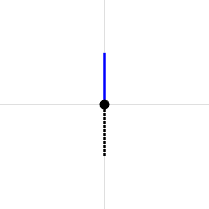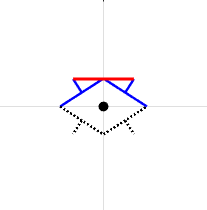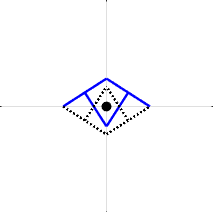

The commonality between the solutions is that the contralateral leg positions are mirrored and with further exploration, we can show that ***all birfurcation points discussed in the kinematic analysis section fail to have any form of connection*** as shown here. `This form will hence be used in the new solution classifier for the numerically evaluated solver.`

double(subs(expr01_det_sym, [a, b1, b2, g], [1, 0, 0, pi/4]))

ans = 0

This robot configuration is shown below (along with some other configurations for the A sweep shown on the right):

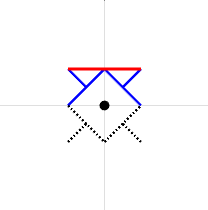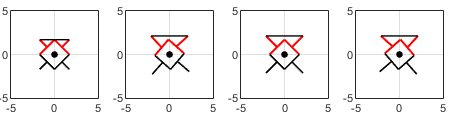

## Breaking of symmetry

In this section, we shall discuss why our problem non-compatible with the current Geometric Mechanics paradigm. I shall quote sections of this paper (in italicized font) [https://link.springer.com/article/10.1140/epjst/e2015-50085-y](https://link.springer.com/article/10.1140/epjst/e2015-50085-y)  to ease this process.

Page 3, Para 2 -- *"In this paradigm, two assumptions about system behavior are often used to frame the analysis. First, that the system’s shape is fully controlled (i.e. the shape can be regarded as an input), thus letting the connection induce a Jacobian from control inputs to the resulting position velocity, modulo any second-order momentum effects. Second, that when expressed in body coordinates the system constraints are invariant with respect to the position; intuitively, this leads to the concept that a shape change that pulls the system “forward” will always do so, regardless of how the system is located and oriented."*

The system for us is not fully controlled -- body angle $2\gamma$ is uncontrolled and as the reconstruction equation currently stands it has been added as a fourth position variable instead of a robot shape variable since $\dot{\gamma}$ is constrained (and appears in both vector-constraints on the global leg-positions). Secondly, the constraints in our case involve ***no-slip ***for two electroadhesive legs that we consider in the stride, and hence, need to be expressed globally (meaning, we need a rest-frame to write out the constraints). Due to this, **the connection depends on** $\mathbf{\theta}$ **and** ***how the system is located and oriented matters to how it moves***.

Page 9, Section 3.1.3, Para 1 -- "*Many locomoting systems’ equations of motion are dictated by linear constraints defined in their body frame (i.e., which are symmetric with respect to left group actions). If there are as many of these constraints as there are dimensions in the position space, they define a principal connection (Sect. C.3) A on the configuration space.*"

As mentioned earlier, we *can't *express the system constraints in the body frame. All of our our constraints need a global rest-frame description.

Page 40, Section C.3, Paras 1,2,&3 -- "*A principal connection *$\mathcal{A}$* is a constraint distribution on a principal fiber bundle (Sect. A.5) that is both complementary to the space of pure fiber velocities and symmetric with respect to group actions on the fiber space [3]. The first property means that the distribution contains as many independent vector fields as there are dimensions in the base space, and that no vectors in these fields are aligned purely in the fiber direction. The second property means that the connection needs only to be defined for a single fiber value (such as the group identity *$\mathbf{e}$*), after which it can be generated at any other fiber value via the group’s lifted actions (A.2). Principal connections are encoded as vector-valued one-forms on the fiber bundle that output elements of *$T_e G$*. The kernels (null-spaces) of these one-forms contain the velocities allowed by the system constraints,*


$$\mathcal{D}_\mathcal{A} (q) = \{\dot{q} \in T_q Q | \mathcal{A}(q)\dot{q} = \mathbf{0} \}.$$


*Because this distribution is complementary to the space of pure fiber velocities, vectors in *$\mathcal{D}_\mathcal{A}$* are fully specified by their base-space components: at a configuration *$q = (g, r)$*, for any base velocity *$\dot{r} \in T_r B$* there is a unique fiber velocity *$\dot{g} \in T_g G$* for which the total velocity *$\dot{q} = (\dot{g},\dot{r})$* satisfies the null-space condition in (C.1) [3]. This attribute allows the connection to be expressed in a local form as a one-form *$\mathbf{A}$* that maps from base velocities to their associated fiber velocities.*"

The constraint equations are expressed as a linear functions of the $\mathbf{SE(2)}$**velocities **$\mathbf{\dot{g}}$ (*fiber velocities*) and **shape velocities** $\mathbf{\dot{r}}$ (*base velocities*). The $1^{st}$ property on the existence of a principal connection $\mathcal{A}$ suggests that we the columns in our $\mathbf{A}$ matrix are independent and none of our shape velocities directly modulate global velocities. We satisfy the second part of this, but the first part implies a connection always exists which is not true in our case. As introduced in 'kinematic motion planning for eCLARI analysis' section and mathematically shown in the 'inverse of $\omega_1$' section, we don't always have a connection at our bifurcation points. Outside this, connection exists but, can have more than one solution -- for a given set of leg angles, for most cases our robot has '*short and fat*' $\gamma
$ configuration and a 'tall and skinny' $\gamma$ configuration.

The second property is already addressed, but to repeat, ***our no-slip constraint can't be expressed in the body-frame***.

## eCLAIR kinematics

The best way to get the local connection would be through the leg velocity constraints (refer "se2_toyproblems.mlx" in the same repository for a larger version of the answer). There are size distinct, level-2 submanifolds for a 4-legged system. We shall explore each!

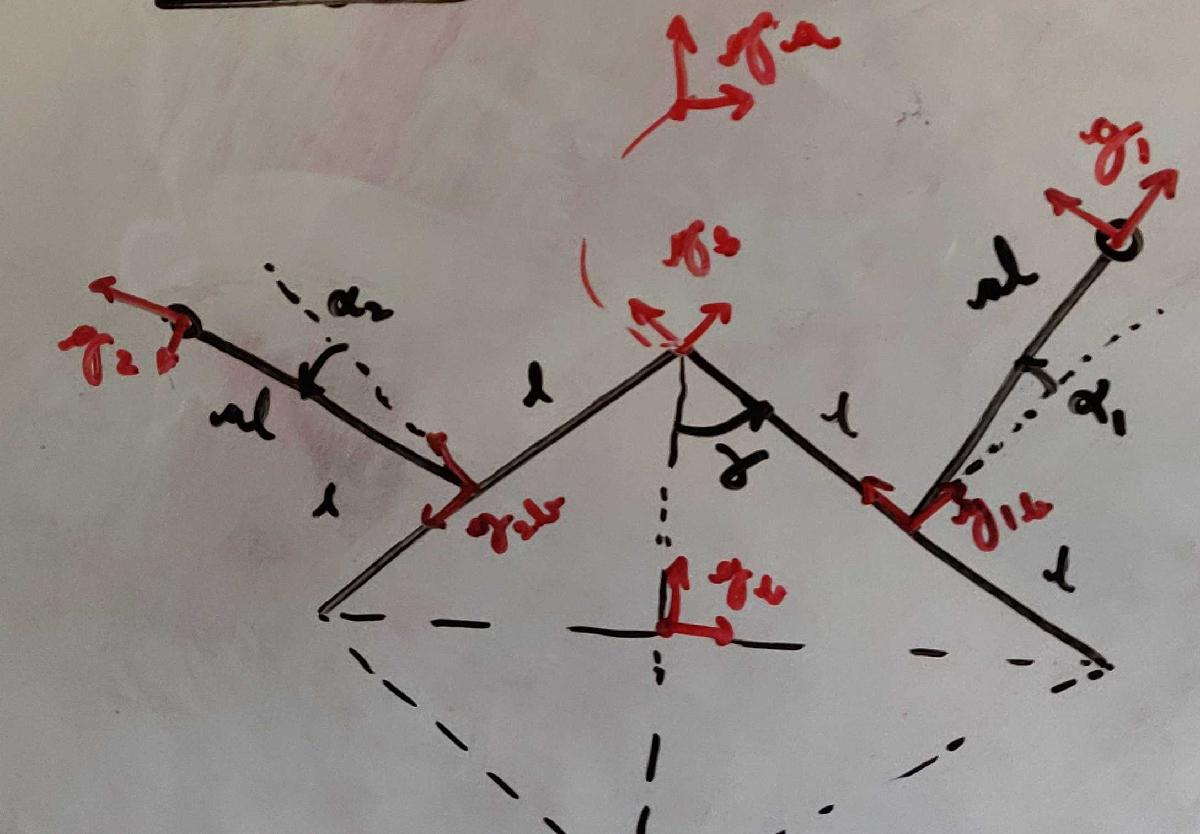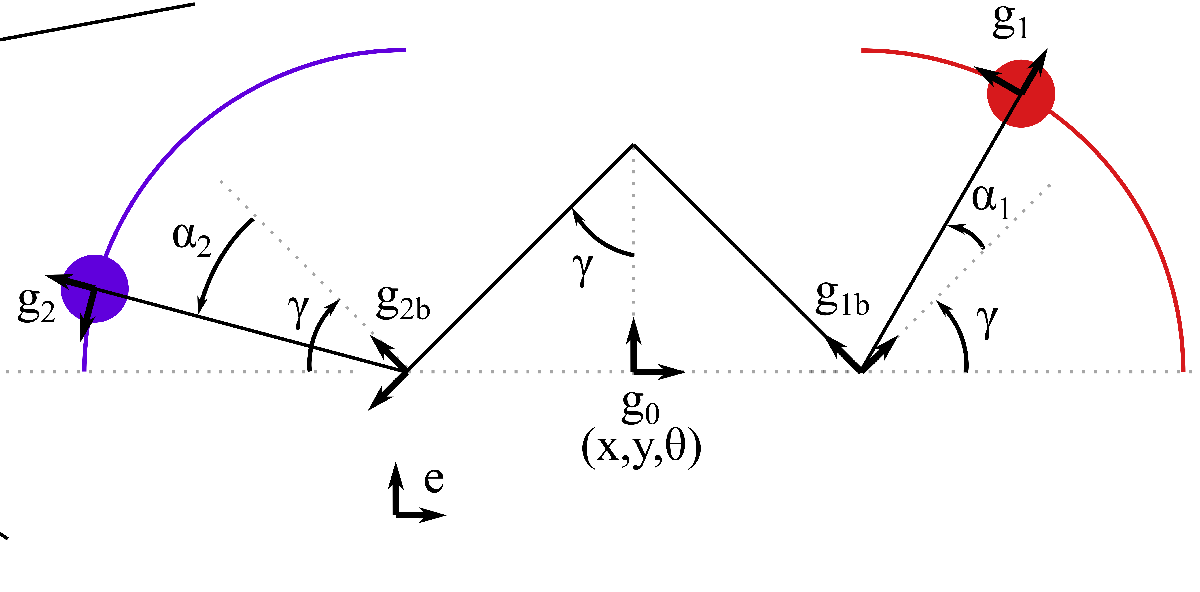

syms x y theta u v beta real

v2M_SE2 = @(v) [cos(v(3)), -sin(v(3)), v(1);
                sin(v(3)),  cos(v(3)), v(2);
                        0,         0,    1];

M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);

L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 

T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g);

g_vec = [x;
         y;
         theta];
h_vec = [u;
         v;
         beta];

g_mat = v2M_SE2(g_vec);

T_g_to_T_hg = T_gL_h(g_vec, h_vec);
T_g_to_T_gh = T_gR_h(g_vec, h_vec);

gInv_mat = simplify(inv(g_mat), 'Steps', 10);
gInv_vec = M2v_SE2(gInv_mat);

TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]));
TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]));
AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10);

theta_circ = [0,0,1]'; x_circ = [1,0,0]'; y_circ = [0,1,0]';

syms l gamma real
h_b__1b = [l*[sin(gamma); cos(gamma)]; gamma]

$$h\_b\_\_1b = \left(\begin{array}{c} l\,\sin\left(\gamma \right)\\ l\,\cos\left(\gamma \right)\\ \gamma \end{array}\right)$$

h_b__2b = [l*[-sin(gamma); cos(gamma)]; pi-gamma]

$$h\_b\_\_2b = \left(\begin{array}{c} -l\,\sin\left(\gamma \right)\\ l\,\cos\left(\gamma \right)\\ \pi -\gamma \end{array}\right)$$

h_b__3b = [l*[-sin(gamma); -cos(gamma)]; pi+gamma]

$$h\_b\_\_3b = \left(\begin{array}{c} -l\,\sin\left(\gamma \right)\\ -l\,\cos\left(\gamma \right)\\ \gamma +\pi \end{array}\right)$$

h_b__4b = [l*[sin(gamma); -cos(gamma)]; -gamma]

$$h\_b\_\_4b = \left(\begin{array}{c} l\,\sin\left(\gamma \right)\\ -l\,\cos\left(\gamma \right)\\ -\gamma \end{array}\right)$$

syms a real positive
syms alpha_i alpha_1 alpha_2 alpha_3 alpha_4 real
h_ib__i = [a*l*[cos(alpha_i); sin(alpha_i)]; alpha_i]

$$h\_ib\_\_i = \left(\begin{array}{c} a\,l\,\cos\left(\alpha_{i}\right)\\ a\,l\,\sin\left(\alpha_{i}\right)\\ \alpha_{i} \end{array}\right)$$

h_1b__1 = subs(h_ib__i, alpha_i, alpha_1)

$$h\_1b\_\_1 = \left(\begin{array}{c} a\,l\,\cos\left(\alpha_{1}\right)\\ a\,l\,\sin\left(\alpha_{1}\right)\\ \alpha_{1} \end{array}\right)$$

h_2b__2 = subs(h_ib__i, alpha_i, alpha_2)

$$h\_2b\_\_2 = \left(\begin{array}{c} a\,l\,\cos\left(\alpha_{2}\right)\\ a\,l\,\sin\left(\alpha_{2}\right)\\ \alpha_{2} \end{array}\right)$$

h_3b__3 = subs(h_ib__i, alpha_i, alpha_3)

$$h\_3b\_\_3 = \left(\begin{array}{c} a\,l\,\cos\left(\alpha_{3}\right)\\ a\,l\,\sin\left(\alpha_{3}\right)\\ \alpha_{3} \end{array}\right)$$

h_4b__4 = subs(h_ib__i, alpha_i, alpha_4)

$$h\_4b\_\_4 = \left(\begin{array}{c} a\,l\,\cos\left(\alpha_{4}\right)\\ a\,l\,\sin\left(\alpha_{4}\right)\\ \alpha_{4} \end{array}\right)$$

J_ib__i = AdjInvMap(h_ib__i)

$$J\_ib\_\_i = \left(\begin{array}{ccc} \cos\left(\alpha_{i}\right) & \sin\left(\alpha_{i}\right) & 0\\ -\sin\left(\alpha_{i}\right) & \cos\left(\alpha_{i}\right) & a\,l\\ 0 & 0 & 1 \end{array}\right)$$

J_ib__i_func = matlabFunction(J_ib__i, 'Vars', [a,l,alpha_i]);

J_1b__1 = J_ib__i_func(a,l,alpha_1)

$$J\_1b\_\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & a\,l\\ 0 & 0 & 1 \end{array}\right)$$

J_2b__2 = J_ib__i_func(a,l,alpha_2)

$$J\_2b\_\_2 = \left(\begin{array}{ccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & a\,l\\ 0 & 0 & 1 \end{array}\right)$$

J_3b__3 = J_ib__i_func(a,l,alpha_3)

$$J\_3b\_\_3 = \left(\begin{array}{ccc} \cos\left(\alpha_{3}\right) & \sin\left(\alpha_{3}\right) & 0\\ -\sin\left(\alpha_{3}\right) & \cos\left(\alpha_{3}\right) & a\,l\\ 0 & 0 & 1 \end{array}\right)$$

J_4b__4 = J_ib__i_func(a,l,alpha_4)

$$J\_4b\_\_4 = \left(\begin{array}{ccc} \cos\left(\alpha_{4}\right) & \sin\left(\alpha_{4}\right) & 0\\ -\sin\left(\alpha_{4}\right) & \cos\left(\alpha_{4}\right) & a\,l\\ 0 & 0 & 1 \end{array}\right)$$

J_1b__2 = zeros(3,3); % just a bunch of zeroes to control the wrong leg
J_1b__3 = zeros(3,3);
J_1b__4 = zeros(3,3);
J_2b__1 = zeros(3,3);
J_2b__3 = zeros(3,3);
J_2b__4 = zeros(3,3);
J_3b__1 = zeros(3,3);
J_3b__2 = zeros(3,3);
J_3b__4 = zeros(3,3);
J_4b__1 = zeros(3,3);
J_4b__2 = zeros(3,3);
J_4b__3 = zeros(3,3);

% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % TRANSFORM VALIDAITON COMPLETE
% We need these transforms to plot the system as a sanity check
h_b__s12 = [0, 2*l*cos(gamma), gamma]';
h_b__s34 = [0, -2*l*cos(gamma), pi+gamma];

h_s12__1b = [0, -l, 0]'

$$h\_s12\_\_1b = \left(\begin{array}{c} 0\\ -l\\ 0 \end{array}\right)$$

h_s12__2b = [l*[cos(3*pi/2 - 2*gamma); sin(3*pi/2 - 2*gamma)]; pi-2*gamma]

$$h\_s12\_\_2b = \left(\begin{array}{c} l\,\cos\left(2\,\gamma -\frac{3\,\pi }{2}\right)\\ -l\,\sin\left(2\,\gamma -\frac{3\,\pi }{2}\right)\\ \pi -2\,\gamma \end{array}\right)$$

h_s34__3b = h_s12__1b

$$h\_s34\_\_3b = \left(\begin{array}{c} 0\\ -l\\ 0 \end{array}\right)$$

h_s34__4b = h_s12__2b

$$h\_s34\_\_4b = \left(\begin{array}{c} l\,\cos\left(2\,\gamma -\frac{3\,\pi }{2}\right)\\ -l\,\sin\left(2\,\gamma -\frac{3\,\pi }{2}\right)\\ \pi -2\,\gamma \end{array}\right)$$

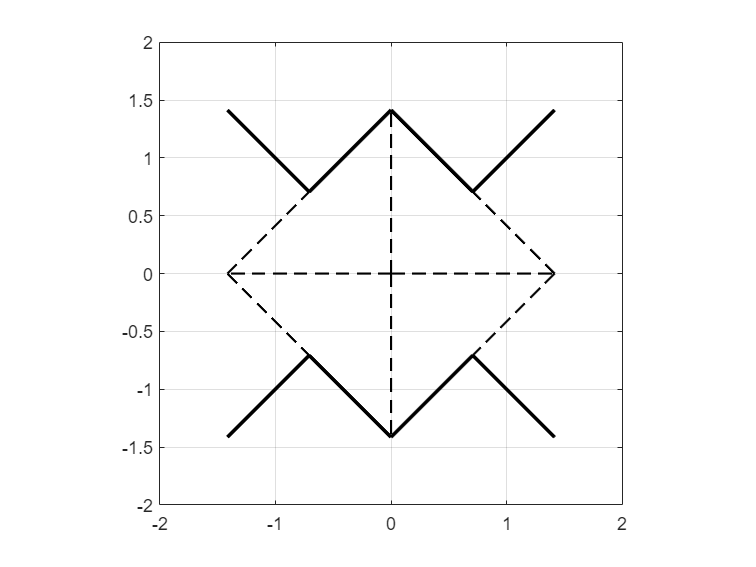

h_b__1 = M2v_SE2(v2M_SE2(h_b__1b)*v2M_SE2(h_1b__1));
h_b__2 = M2v_SE2(v2M_SE2(h_b__2b)*v2M_SE2(h_2b__2));
h_b__3 = M2v_SE2(v2M_SE2(h_b__3b)*v2M_SE2(h_3b__3));
h_b__4 = M2v_SE2(v2M_SE2(h_b__4b)*v2M_SE2(h_4b__4));

% Let's introduce a few other frames to complete the figure
h_b__s23 = [-2*l*sin(gamma),0,pi-gamma];
h_b__s41 = [2*l*sin(gamma),0,-gamma];

sprawljoint12_x = [0 h_b__s12(1)]; sprawljoint12_y = [0 h_b__s12(2)];
sprawljoint34_x = [0 h_b__s34(1)]; sprawljoint34_y = [0 h_b__s34(2)];
sprawljoint23_x = [0 h_b__s23(1)]; sprawljoint23_y = [0 h_b__s23(2)];
sprawljoint41_x = [0 h_b__s41(1)]; sprawljoint41_y = [0 h_b__s41(2)];

sprawl12_legbase1_x = [h_b__s12(1) h_b__1b(1)]; sprawl12_legbase1_y = [h_b__s12(2) h_b__1b(2)];
sprawl12_legbase2_x = [h_b__s12(1) h_b__2b(1)]; sprawl12_legbase2_y = [h_b__s12(2) h_b__2b(2)];
sprawl34_legbase3_x = [h_b__s34(1) h_b__3b(1)]; sprawl34_legbase3_y = [h_b__s34(2) h_b__3b(2)];
sprawl34_legbase4_x = [h_b__s34(1) h_b__4b(1)]; sprawl34_legbase4_y = [h_b__s34(2) h_b__4b(2)];

sprawl23_legbase2_x = [h_b__s23(1) h_b__2b(1)]; sprawl23_legbase2_y = [h_b__s23(2) h_b__2b(2)];
sprawl23_legbase3_x = [h_b__s23(1) h_b__3b(1)]; sprawl23_legbase3_y = [h_b__s23(2) h_b__3b(2)];
sprawl41_legbase1_x = [h_b__s41(1) h_b__1b(1)]; sprawl41_legbase1_y = [h_b__s41(2) h_b__1b(2)];
sprawl41_legbase4_x = [h_b__s41(1) h_b__4b(1)]; sprawl41_legbase4_y = [h_b__s41(2) h_b__4b(2)];

legbase1_leg1_x =  [h_b__1b(1) h_b__1(1)]; legbase1_leg1_y =  [h_b__1b(2) h_b__1(2)];
legbase2_leg2_x =  [h_b__2b(1) h_b__2(1)]; legbase2_leg2_y =  [h_b__2b(2) h_b__2(2)];
legbase3_leg3_x =  [h_b__3b(1) h_b__3(1)]; legbase3_leg3_y =  [h_b__3b(2) h_b__3(2)];
legbase4_leg4_x =  [h_b__4b(1) h_b__4(1)]; legbase4_leg4_y =  [h_b__4b(2) h_b__4(2)];

sprawljoint12_x = double(subs(sprawljoint12_x,[gamma, l],[pi/4, 1])); % equilibrium position of the robot
sprawljoint12_y = double(subs(sprawljoint12_y,[gamma, l],[pi/4, 1]));
sprawljoint34_x = double(subs(sprawljoint34_x,[gamma, l],[pi/4, 1]));
sprawljoint34_y = double(subs(sprawljoint34_y,[gamma, l],[pi/4, 1]));

sprawljoint23_x = double(subs(sprawljoint23_x,[gamma, l],[pi/4, 1]));
sprawljoint23_y = double(subs(sprawljoint23_y,[gamma, l],[pi/4, 1]));
sprawljoint41_x = double(subs(sprawljoint41_x,[gamma, l],[pi/4, 1]));
sprawljoint41_y = double(subs(sprawljoint41_y,[gamma, l],[pi/4, 1]));

sprawl12_legbase1_x = double(subs(sprawl12_legbase1_x,[gamma, l],[pi/4, 1]));
sprawl12_legbase1_y = double(subs(sprawl12_legbase1_y,[gamma, l],[pi/4, 1]));
sprawl12_legbase2_x = double(subs(sprawl12_legbase2_x,[gamma, l],[pi/4, 1]));
sprawl12_legbase2_y = double(subs(sprawl12_legbase2_y,[gamma, l],[pi/4, 1]));
sprawl34_legbase3_x = double(subs(sprawl34_legbase3_x,[gamma, l],[pi/4, 1]));
sprawl34_legbase3_y = double(subs(sprawl34_legbase3_y,[gamma, l],[pi/4, 1]));
sprawl34_legbase4_x = double(subs(sprawl34_legbase4_x,[gamma, l],[pi/4, 1]));
sprawl34_legbase4_y = double(subs(sprawl34_legbase4_y,[gamma, l],[pi/4, 1]));
sprawl23_legbase2_x = double(subs(sprawl23_legbase2_x,[gamma, l],[pi/4, 1]));
sprawl23_legbase2_y = double(subs(sprawl23_legbase2_y,[gamma, l],[pi/4, 1]));
sprawl23_legbase3_x = double(subs(sprawl23_legbase3_x,[gamma, l],[pi/4, 1]));
sprawl23_legbase3_y = double(subs(sprawl23_legbase3_y,[gamma, l],[pi/4, 1]));
sprawl41_legbase1_x = double(subs(sprawl41_legbase1_x,[gamma, l],[pi/4, 1]));
sprawl41_legbase1_y = double(subs(sprawl41_legbase1_y,[gamma, l],[pi/4, 1]));
sprawl41_legbase4_x = double(subs(sprawl41_legbase4_x,[gamma, l],[pi/4, 1]));
sprawl41_legbase4_y = double(subs(sprawl41_legbase4_y,[gamma, l],[pi/4, 1]));

legbase1_leg1_x =  double(subs(legbase1_leg1_x,[gamma, a, l, alpha_1],[pi/4, 1, 1, 0]));
legbase1_leg1_y =  double(subs(legbase1_leg1_y,[gamma, a, l, alpha_1],[pi/4, 1, 1, 0]));
legbase2_leg2_x =  double(subs(legbase2_leg2_x,[gamma, a, l, alpha_2],[pi/4, 1, 1, 0]));
legbase2_leg2_y =  double(subs(legbase2_leg2_y,[gamma, a, l, alpha_2],[pi/4, 1, 1, 0]));

legbase3_leg3_x =  double(subs(legbase3_leg3_x,[gamma, a, l, alpha_3],[pi/4, 1, 1, 0]));
legbase3_leg3_y =  double(subs(legbase3_leg3_y,[gamma, a, l, alpha_3],[pi/4, 1, 1, 0]));
legbase4_leg4_x =  double(subs(legbase4_leg4_x,[gamma, a, l, alpha_4],[pi/4, 1, 1, 0]));
legbase4_leg4_y =  double(subs(legbase4_leg4_y,[gamma, a, l, alpha_4],[pi/4, 1, 1, 0]));

figure()

% Plot to each vertex
plot(sprawljoint12_x,sprawljoint12_y,'k--','LineWidth',1.2);
hold on; grid on;
plot(sprawljoint34_x,sprawljoint34_y,'k--','LineWidth',1.2);
plot(sprawljoint23_x,sprawljoint23_y,'k--','LineWidth',1.2);
plot(sprawljoint41_x,sprawljoint41_y,'k--','LineWidth',1.2);

% Plot the sprawl to each leg base
plot(sprawl12_legbase1_x,sprawl12_legbase1_y,'k','LineWidth',2);
plot(sprawl12_legbase2_x,sprawl12_legbase2_y,'k','LineWidth',2);
plot(sprawl34_legbase3_x,sprawl34_legbase3_y,'k','LineWidth',2);
plot(sprawl34_legbase4_x,sprawl34_legbase4_y,'k','LineWidth',2);
plot(sprawl23_legbase2_x,sprawl23_legbase2_y,'k--','LineWidth',1.2);
plot(sprawl23_legbase3_x,sprawl23_legbase3_y,'k--','LineWidth',1.2);
plot(sprawl41_legbase1_x,sprawl41_legbase1_y,'k--','LineWidth',1.2);
plot(sprawl41_legbase4_x,sprawl41_legbase4_y,'k--','LineWidth',1.2);

% Plot each leg
plot(legbase1_leg1_x,legbase1_leg1_y,'k','LineWidth',2);
plot(legbase2_leg2_x,legbase2_leg2_y,'k','LineWidth',2);
plot(legbase3_leg3_x,legbase3_leg3_y,'k','LineWidth',2);
plot(legbase4_leg4_x,legbase4_leg4_y,'k','LineWidth',2);

axis equal square; ylim([-2, 2]); xlim([-2, 2]);

% Obtain the squared, inter-leg distance for each level to contact mode
C = [eye(2), zeros(2,1);
        zeros(1,3)];
k1 = C*h_b__1;
k2 = C*h_b__2;
k3 = C*h_b__3;
k4 = C*h_b__4;
ksq_12 = simplify((k2 - k1)'*(k2 - k1), 'Steps', 10);
ksq_23 = simplify((k3 - k2)'*(k3 - k2), 'Steps', 10);
ksq_34 = simplify((k4 - k3)'*(k4 - k3), 'Steps', 10);
ksq_41 = simplify((k1 - k4)'*(k1 - k4), 'Steps', 10);
ksq_13 = simplify((k3 - k1)'*(k3 - k1), 'Steps', 10);
ksq_24 = simplify((k4 - k2)'*(k4 - k2), 'Steps', 10);

ksq_12_func = matlabFunction(ksq_12,'Vars',[a,l,alpha_1,alpha_2,gamma]);
ksq_23_func = matlabFunction(ksq_23,'Vars',[a,l,alpha_2,alpha_3,gamma]);
ksq_34_func = matlabFunction(ksq_34,'Vars',[a,l,alpha_3,alpha_4,gamma]);
ksq_41_func = matlabFunction(ksq_41,'Vars',[a,l,alpha_4,alpha_1,gamma]);
ksq_13_func = matlabFunction(ksq_13,'Vars',[a,l,alpha_1,alpha_3,gamma]);
ksq_24_func = matlabFunction(ksq_24,'Vars',[a,l,alpha_2,alpha_4,gamma]);

% Initialize parameters and other stuff you need
dnum = 31; %10 %25 %50 %75 %100 % some example values (use lowest value 
                                 % for testing

% Tolerance for numerical checking
tol = 1e-10; % this needs to be iteratively set to find the smallest (not really)
% that works for you. By "not really" I mean you can do this more
% imprecisely if you want.

% Define the range for each shape mode and other system parameters:
aa = 1;                                 % leg to half link length ratio
ll = 1;                                 % half link length

ank = pi/4;                            % symmetric leg ankle limit
sank = [deg2rad(0),deg2rad(90)];            % sprawl limits (ordered; make sure
                                            % they are realistic)
% the standard limits for the system to go from a vertical line to a
% horizontal line would be 0degs to 90 degs -- but this scales the vector
% field poorly.

a1 = linspace(-ank,ank,dnum);          % top right leg angle
a2 = a1;                               % top left leg angle
a3 = a2;                               % bottom left leg angle
a4 = a3;                               % bottom right leg angle

g = linspace(sank(1),sank(2),dnum);    % sprawl angle

% Get the equilibrium sprawl angle using the tolerance set earlier
idx_geq = find(abs(g) < mean(sank) + tol & abs(g) > mean(sank) - tol);

[a1,a2,a3,a4,g] = ndgrid(a1,a2,a3,a4,g);         % create a 5D grid of values in each 
                                                   % shape

% Compute the ksq_sweep outside the loop:
ksq_12_sweep = ksq_12_func(aa,ll,a1,a2,g);
ksq_23_sweep = ksq_23_func(aa,ll,a2,a3,g);
ksq_34_sweep = ksq_34_func(aa,ll,a3,a4,g);
ksq_41_sweep = ksq_41_func(aa,ll,a4,a1,g);
ksq_13_sweep = ksq_13_func(aa,ll,a1,a3,g);
ksq_24_sweep = ksq_24_func(aa,ll,a2,a4,g);

% Let's get the limits by obtaining the maximum and minimum distance
% achievable in each contact mode -- prolly ones in the 13 and 24 contact
% states.
maxksq_12 = max(ksq_12_sweep,[],'all'); minksq_12 = min(ksq_12_sweep,[],'all');
maxksq_23 = max(ksq_23_sweep,[],'all'); minksq_23 = min(ksq_23_sweep,[],'all');
maxksq_34 = max(ksq_34_sweep,[],'all'); minksq_34 = min(ksq_34_sweep,[],'all');
maxksq_41 = max(ksq_41_sweep,[],'all'); minksq_41 = min(ksq_41_sweep,[],'all');
maxksq_13 = max(ksq_13_sweep,[],'all'); minksq_13 = min(ksq_13_sweep,[],'all');
maxksq_24 = max(ksq_24_sweep,[],'all'); minksq_24 = min(ksq_24_sweep,[],'all');
maxksq = max([maxksq_12,maxksq_23,maxksq_34,maxksq_41,maxksq_13,maxksq_24],[],'all');
minksq = max([minksq_12,minksq_23,minksq_34,minksq_41,minksq_13,minksq_24],[],'all');

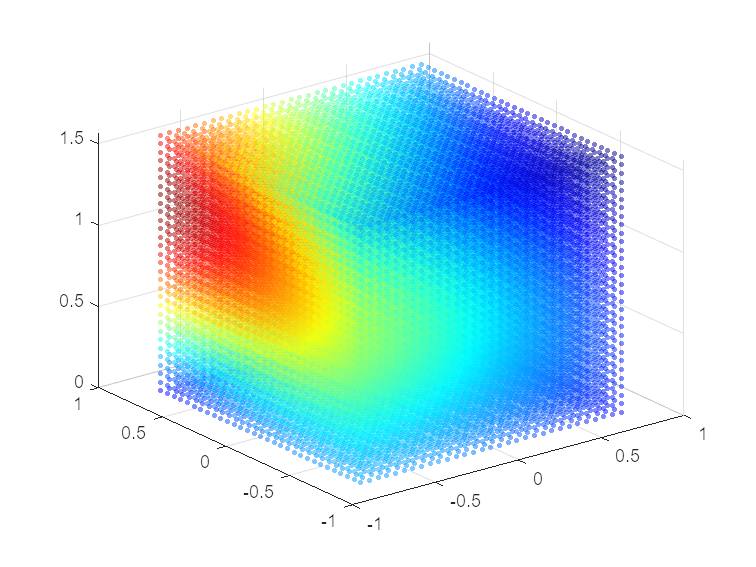

% Plot the distance landscape; note that the conservation law for the
% locomotion would be riding constant inter-leg distance until a contact
% mode switch happens.
figure()
scatter3(reshape(a1(:,:,1,1,:),1,dnum*dnum*dnum),...
    reshape(a2(:,:,1,1,:),1,dnum*dnum*dnum),...
    reshape(g(:,:,1,1,:),1,dnum*dnum*dnum),...
    10,reshape(ksq_12_sweep(:,:,1,1,:),1,dnum*dnum*dnum),...
    'filled','MarkerFaceAlpha',0.5,'MarkerEdgeColor','none','Marker','o');
colormap(jet); 

clim([minksq_12 maxksq_12]);

Unrecognized function or variable 'clim'.

colorbar('ylim',[minksq maxksq]);
view(-60,15);
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
zlabel('$\gamma$','Interpreter','latex',FontSize=20);
title('$k^2_{12}$','Interpreter','latex',FontSize=20);
figure()
scatter3(reshape(a3(1,1,:,:,:),1,dnum*dnum*dnum),...
    reshape(a4(1,1,:,:,:),1,dnum*dnum*dnum),...
    reshape(g(1,1,:,:,:),1,dnum*dnum*dnum),...
    10,reshape(ksq_34_sweep(1,1,:,:,:),1,dnum*dnum*dnum),...
    'filled','MarkerFaceAlpha',0.5,'MarkerEdgeColor','none','Marker','o');
colormap(jet);
clim([minksq_34 maxksq_34]);
colorbar('ylim',[minksq maxksq]); 
view(-60,15);
xlabel('$\alpha_3$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_4$','Interpreter','latex',FontSize=20);
zlabel('$\gamma$','Interpreter','latex',FontSize=20);
title('$k^2_{34}$','Interpreter','latex',FontSize=20);
figure()
scatter3(reshape(a2(1,:,:,1,:),1,dnum*dnum*dnum),...
    reshape(a3(1,:,:,1,:),1,dnum*dnum*dnum),...
    reshape(g(1,:,:,1,:),1,dnum*dnum*dnum),...
    10,reshape(ksq_23_sweep(1,:,:,1,:),1,dnum*dnum*dnum),...
    'filled','MarkerFaceAlpha',0.5,'MarkerEdgeColor','none','Marker','o');
colormap(jet);
clim([minksq_23 maxksq_23]);
colorbar('ylim',[minksq maxksq]); 
view(-60,15);
xlabel('$\alpha_2$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_3$','Interpreter','latex',FontSize=20);
zlabel('$\gamma$','Interpreter','latex',FontSize=20);
title('$k^2_{23}$','Interpreter','latex',FontSize=20);
figure()
scatter3(reshape(a4(:,1,1,:,:),1,dnum*dnum*dnum),...
    reshape(a1(:,1,1,:,:),1,dnum*dnum*dnum),...
    reshape(g(:,1,1,:,:),1,dnum*dnum*dnum),...
    10,reshape(ksq_41_sweep(:,1,1,:,:),1,dnum*dnum*dnum),...
    'filled','MarkerFaceAlpha',0.5,'MarkerEdgeColor','none','Marker','o');
colormap(jet);
clim([minksq_41 maxksq_41]);
colorbar('ylim',[minksq maxksq]); 
view(-60,15);
xlabel('$\alpha_4$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_1$','Interpreter','latex',FontSize=20);
zlabel('$\gamma$','Interpreter','latex',FontSize=20);
title('$k^2_{41}$','Interpreter','latex',FontSize=20);
figure()
scatter3(reshape(a1(:,1,:,1,:),1,dnum*dnum*dnum),...
    reshape(a3(:,1,:,1,:),1,dnum*dnum*dnum),...
    reshape(g(:,1,:,1,:),1,dnum*dnum*dnum),...
    10,reshape(ksq_13_sweep(:,1,:,1,:),1,dnum*dnum*dnum),...
    'filled','MarkerFaceAlpha',0.5,'MarkerEdgeColor','none','Marker','o');
colormap(jet);
clim([minksq_13 maxksq_13]);
colorbar('ylim',[minksq maxksq]); 
% view(-60,15);
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_3$','Interpreter','latex',FontSize=20);
zlabel('$\gamma$','Interpreter','latex',FontSize=20);
title('$k^2_{13}$','Interpreter','latex',FontSize=20);
figure()
scatter3(reshape(a2(1,:,1,:,:),1,dnum*dnum*dnum),...
    reshape(a4(1,:,1,:,:),1,dnum*dnum*dnum),...
    reshape(g(1,:,1,:,:),1,dnum*dnum*dnum),...
    10,reshape(ksq_24_sweep(1,:,1,:,:),1,dnum*dnum*dnum),...
    'filled','MarkerFaceAlpha',0.5,'MarkerEdgeColor','none','Marker','o');
colormap(jet);
clim([minksq_24 maxksq_24]);
colorbar('ylim',[minksq maxksq]); 
% view(-60,15);
xlabel('$\alpha_2$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_4$','Interpreter','latex',FontSize=20);
zlabel('$\gamma$','Interpreter','latex',FontSize=20);
title('$k^2_{24}$','Interpreter','latex',FontSize=20);

Since we place the robot in it's equilibrium configuration, we can plot the $k^2$ values at $\gamma = \frac{\pi}{4}$ for each of these systems. I think I need to animate this as well to highlight the two different branches of solutions for each contact state.

% The mean configuration gamma value, should be somewhere right in the
% middle.
figure()
surf(reshape(a1(:,:,1,1,idx_geq),dnum,dnum),...
    reshape(a2(:,:,1,1,idx_geq),dnum,dnum),...
    reshape(ksq_12_sweep(:,:,1,1,idx_geq),dnum,dnum),...
    'EdgeColor','none');

Unrecognized function or variable 'a1'.

axis equal tight; hold on; view(2);
colormap(jet);
clim([minksq_12 maxksq_12]); colorbar('ylim',[minksq maxksq]); 
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
title('$k^2_{12}(\gamma = \frac{\pi}{4})$','Interpreter','latex',FontSize=20);
figure()
surf(reshape(a3(1,1,:,:,idx_geq),dnum,dnum),...
    reshape(a4(1,1,:,:,idx_geq),dnum,dnum),...
    reshape(ksq_34_sweep(1,1,:,:,idx_geq),dnum,dnum),...
    'EdgeColor','none');
axis equal tight; hold on; view(2);
colormap(jet);
clim([minksq_34 maxksq_34]); colorbar('ylim',[minksq maxksq]); 
xlabel('$\alpha_3$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_4$','Interpreter','latex',FontSize=20);
title('$k^2_{34}(\gamma = \frac{\pi}{4})$','Interpreter','latex',FontSize=20);
figure()
surf(reshape(a2(1,:,:,1,idx_geq),dnum,dnum),...
    reshape(a3(1,:,:,1,idx_geq),dnum,dnum),...
    reshape(ksq_23_sweep(1,:,:,1,idx_geq),dnum,dnum),...
    'EdgeColor','none');
axis equal tight; hold on; view(2);
colormap(jet);
clim([minksq_23 maxksq_23]); colorbar('ylim',[minksq maxksq]); 
xlabel('$\alpha_2$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_3$','Interpreter','latex',FontSize=20);
title('$k^2_{23}(\gamma = \frac{\pi}{4})$','Interpreter','latex',FontSize=20);
figure()
surf(reshape(a4(:,1,1,:,idx_geq),dnum,dnum),...
    reshape(a1(:,1,1,:,idx_geq),dnum,dnum),...
    reshape(ksq_41_sweep(:,1,1,:,idx_geq),dnum,dnum),...
    'EdgeColor','none');
axis equal tight; hold on; view(2);
colormap(jet);
clim([minksq_41 maxksq_41]); colorbar('ylim',[minksq maxksq]); 
xlabel('$\alpha_4$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_1$','Interpreter','latex',FontSize=20);
title('$k^2_{41}(\gamma = \frac{\pi}{4})$','Interpreter','latex',FontSize=20);
figure()
surf(reshape(a1(:,1,:,1,idx_geq),dnum,dnum),...
    reshape(a3(:,1,:,1,idx_geq),dnum,dnum),...
    reshape(ksq_13_sweep(:,1,:,1,idx_geq),dnum,dnum),...
    'EdgeColor','none');
axis equal tight; hold on; view(2);
colormap(jet);
clim([minksq_13 maxksq_13]); colorbar('ylim',[minksq maxksq]); 
xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_3$','Interpreter','latex',FontSize=20);
title('$k^2_{13}(\gamma = \frac{\pi}{4})$','Interpreter','latex',FontSize=20);
figure()
surf(reshape(a2(1,:,1,:,idx_geq),dnum,dnum),...
    reshape(a4(1,:,1,:,idx_geq),dnum,dnum),...
    reshape(ksq_24_sweep(1,:,1,:,idx_geq),dnum,dnum),...
    'EdgeColor','none');
axis equal tight; hold on; view(2);
colormap(jet);
clim([minksq_24 maxksq_24]); colorbar('ylim',[minksq maxksq]); 
xlabel('$\alpha_2$','Interpreter','latex',FontSize=20);
ylabel('$\alpha_4$','Interpreter','latex',FontSize=20);
title('$k^2_{24}(\gamma = \frac{\pi}{4})$','Interpreter','latex',FontSize=20);

Alright, this is great! We have the barebones working; now it's time to setup an animator. To view the same as a movie from bottom to top!! I'll make this a single video with subplots. Also, the contact states will be grouped into pairs unused legs on either side.

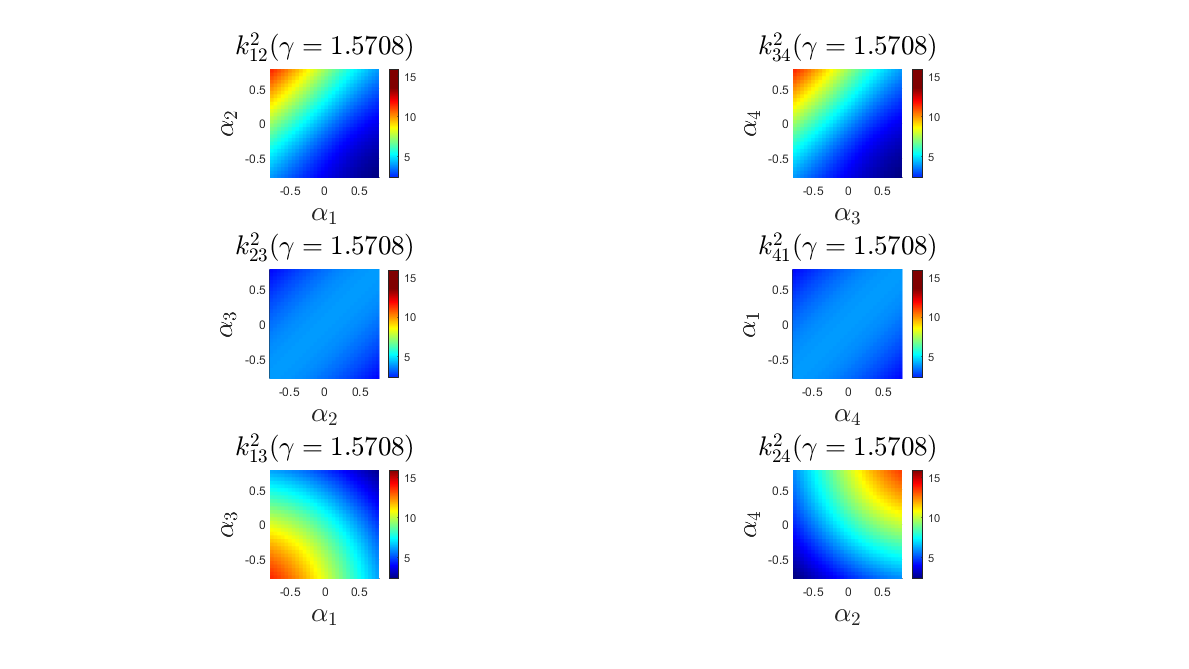

% Create the video object
video = VideoWriter(strcat('ksq_level_2','.mp4'),'MPEG-4'); % creates mp4
% ENTER THE VIDEO TIME HERE:
vidT = 5; % this is coarsely the time, not the exact time.
% Set the framerate
video.FrameRate = round(dnum/5); % roughly takes about 10seconds to complete the video
% Set the quality
video.Quality = 100;
% Open the video
open(video);

% Start plotting
figure('units','pixels','position',[0 0 1920 1080],'Color','w')

for i = 1:dnum
    % Plot and set things up:
    subplot(3,2,1)
    surf(reshape(a1(:,:,1,1,i),dnum,dnum),...
        reshape(a2(:,:,1,1,i),dnum,dnum),...
        reshape(ksq_12_sweep(:,:,1,1,i),dnum,dnum),...
        'EdgeColor','none');
    axis equal tight; hold on; view(2);
    colormap(jet);
    clim([minksq_12 maxksq_12]); colorbar('ylim',[minksq maxksq]); 
    xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
    ylabel('$\alpha_2$','Interpreter','latex',FontSize=20);
    title(['$k^2_{12}(\gamma =', num2str(g(1,1,1,1,i)), ')$'],'Interpreter','latex',FontSize=20);
    subplot(3,2,2)
    surf(reshape(a3(1,1,:,:,i),dnum,dnum),...
        reshape(a4(1,1,:,:,i),dnum,dnum),...
        reshape(ksq_34_sweep(1,1,:,:,i),dnum,dnum),...
        'EdgeColor','none');
    axis equal tight; hold on; view(2);
    colormap(jet);
    clim([minksq_34 maxksq_34]); colorbar('ylim',[minksq maxksq]); 
    xlabel('$\alpha_3$','Interpreter','latex',FontSize=20);
    ylabel('$\alpha_4$','Interpreter','latex',FontSize=20);
    title(['$k^2_{34}(\gamma =', num2str(g(1,1,1,1,i)), ')$'],'Interpreter','latex',FontSize=20);
    subplot(3,2,3)
    surf(reshape(a2(1,:,:,1,i),dnum,dnum),...
        reshape(a3(1,:,:,1,i),dnum,dnum),...
        reshape(ksq_23_sweep(1,:,:,1,i),dnum,dnum),...
        'EdgeColor','none');
    axis equal tight; hold on; view(2);
    colormap(jet);
    clim([minksq_23 maxksq_23]); colorbar('ylim',[minksq maxksq]); 
    xlabel('$\alpha_2$','Interpreter','latex',FontSize=20);
    ylabel('$\alpha_3$','Interpreter','latex',FontSize=20);
    title(['$k^2_{23}(\gamma =', num2str(g(1,1,1,1,i)), ')$'],'Interpreter','latex',FontSize=20);
    subplot(3,2,4)
    surf(reshape(a4(:,1,1,:,i),dnum,dnum),...
        reshape(a1(:,1,1,:,i),dnum,dnum),...
        reshape(ksq_41_sweep(:,1,1,:,i),dnum,dnum),...
        'EdgeColor','none');
    axis equal tight; hold on; view(2);
    colormap(jet);
    clim([minksq_41 maxksq_41]); colorbar('ylim',[minksq maxksq]); 
    xlabel('$\alpha_4$','Interpreter','latex',FontSize=20);
    ylabel('$\alpha_1$','Interpreter','latex',FontSize=20);
    title(['$k^2_{41}(\gamma =', num2str(g(1,1,1,1,i)), ')$'],'Interpreter','latex',FontSize=20);
    subplot(3,2,5)
    surf(reshape(a1(:,1,:,1,i),dnum,dnum),...
        reshape(a3(:,1,:,1,i),dnum,dnum),...
        reshape(ksq_13_sweep(:,1,:,1,i),dnum,dnum),...
        'EdgeColor','none');
    axis equal tight; hold on; view(2);
    colormap(jet);
    clim([minksq_13 maxksq_13]); colorbar('ylim',[minksq maxksq]); 
    xlabel('$\alpha_1$','Interpreter','latex',FontSize=20);
    ylabel('$\alpha_3$','Interpreter','latex',FontSize=20);
    title(['$k^2_{13}(\gamma =', num2str(g(1,1,1,1,i)), ')$'],'Interpreter','latex',FontSize=20);
    subplot(3,2,6)
    surf(reshape(a2(1,:,1,:,i),dnum,dnum),...
        reshape(a4(1,:,1,:,i),dnum,dnum),...
        reshape(ksq_24_sweep(1,:,1,:,i),dnum,dnum),...
        'EdgeColor','none');
    axis equal tight; view(2);
    colormap(jet);
    clim([minksq_24 maxksq_24]); colorbar('ylim',[minksq maxksq]);
    xlabel('$\alpha_2$','Interpreter','latex',FontSize=20);
    ylabel('$\alpha_4$','Interpreter','latex',FontSize=20);
    title(['$k^2_{24}(\gamma =', num2str(g(1,1,1,1,i)), ')$'],'Interpreter','latex',FontSize=20);
    % Draw the current plot since we are in a loop:
    drawnow
    % Capture the frame:
    writeVideo(video,getframe(gcf));
    % Clear the frame if it is not the final one:
    if i ~= dnum
        clf;
    end
end

% Close the video once everything is plotted
close(video);

This is great! Now, we have some tools to tease out the void space. Before we proceed any further with this, let us obtain the connections, etc.

% Get the Jacobians:
J_b__1 = AdjInvMap(h_b__1)
J_b__2 = AdjInvMap(h_b__2)
J_b__3 = AdjInvMap(h_b__3)
J_b__4 = AdjInvMap(h_b__4)
J_s12__1 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__s12)*v2M_SE2(h_s12__1b)*v2M_SE2(h_1b__1)))
J_s12__2 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__s12)*v2M_SE2(h_s12__2b)*v2M_SE2(h_2b__2)))
J_s34__3 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__s34)*v2M_SE2(h_s34__3b)*v2M_SE2(h_3b__3)))
J_s34__4 = AdjInvMap(M2v_SE2(v2M_SE2(h_b__s34)*v2M_SE2(h_s34__4b)*v2M_SE2(h_4b__4)))